# Control Circuit for Radiometer

clear; clc;
f = Func_lib;

## Stock Detector Specs

Detector = {1,.785,60,8571,23.2,3,-.36,-.2,7,.3,2.9,32,56,85,.284,.403};
Diam_d = Detector{1} / 10;%cm
A_j = Detector{2} / 100;%cm^2, area of detector
V_o_dm = Detector{3} / 10^6;%V
S_N_R = Detector{4}; 
Responsivity = Detector{5};
R_det = Detector{6};
TC_Res = Detector{7};
TC_R = Detector{8};
N_V = Detector{9};
N_EP = Detector{10};
Detectivity = Detector{11};
tau = Detector{12};
AFOV_1 = Detector{13};
AFOV_2 = Detector{14};
x1 = Detector{15}%cm

x1 = 0.2840

D_d = Detector{16} * 2.54%cm

D_d = 1.0236

## Package Hole Sizes:

hole_dia = .1*2.54%converted to cm

hole_dia = 0.2540

internal_aperture = false;
tube = true;
external_aperture = false;

#### Location & FOV Info:

r_r = Diam_d / 2; %radius of receiving area,cm
if internal_aperture  == 0
    r_a = hole_dia / 2; %radius of aperture,cm
    if tube == 1
        x1 = 6.9;
        %{
        if external_aperture ==1
            d_a = 0.498;
            r_a = d_a / 2;
        else
            r_a = D_d/2;
        end
        %}
        r_a = D_d/2; 
        AFOV = 2*atand(r_a/x1);
        rat = r_a/x1
    else
        
        r_a = hole_dia / 2; %radius of aperture,cm
    end
else
    ap_d = 1.5/10;
    x1 = .0769; %cm
    r_a = ap_d / 2 %cm
    AFOV = 2*atand(r_a/x1);
end

rat = 0.0742


if exist("AFOV")
    if AFOV_1<AFOV
        AFOV = AFOV_1;
    end
else
    AFOV = AFOV_1;
end

x2 = 9*2.54/2; %estimated distance from sample,cm

if r_a > r_r
    r_s = x2 * tand(AFOV/2) + r_r %radius of visible area, cm
    h_s = 15; %assuming centered on sample,half of height
    wid_s = 3.25; %assuming centered on sample,half of width
    
    R = sqrt((x2^2) + (r_r^2));
    sr = 1/(R^2);
    
    %{
    If r is greater than h_s  and wid_s, entire sample is in view.
    If r is greater than wid_s but not h_s, part of sample is in view.
    If r is less than h_s  and wid_s, all of view is an area of sample.
    %}
    if r_s > h_s
        A_i = 4 * h_s * wid_s;
    elseif r_s > wid_s
        theta = acosd(wid_s/r_s);
        a = (180 - theta)/2;
        w = sqrt((2*(r_s^2))*(1-cosd(a)));
        A_sec = theta*pi*(r_s^2)/360 - .5*w*wid_s;
        A_i = pi*(r_s^2) - 2*A_sec;
    else
        A_i = pi*(r_s^2);
    end
else
    A_i = pi * (r_a^2)
    A_j = A_i;
    R = sqrt((x2^2) + (r_a^2));
    sr = 1/(R^2);
end

r_s = 0.8978

## Basic IR Calcs

#### Range of Temps:

T_range = [273:1273];

#### Range of Wavelengths:

lambda_max = 2898 ./ T_range

lambda_max =    10.6154   10.5766   10.5382   10.5000   10.4621   10.4245   10.3871   10.3500   10.3132   10.2766   10.2403   10.2042   10.1684   10.1329   10.0976   10.0625   10.0277    9.9931    9.9588    9.9247    9.8908    9.8571    9.8237    9.7905    9.7576    9.7248    9.6923    9.6600    9.6279    9.5960    9.5644    9.5329    9.5016    9.4706    9.4397    9.4091    9.3786    9.3484    9.3183    9.2885    9.2588    9.2293    9.2000    9.1709    9.1420    9.1132    9.0846    9.0563    9.0280    9.0000


## Optical Filter

Opt_filt = {[.2:.1:17.5],.91,.91,.039,[0,0,1,1,0,0,0]};
BP_wavelength = Opt_filt{1};
Peak_trans = Opt_filt{2};
Avg_trans = Opt_filt{3}

Avg_trans = 0.9100

Thickness_fil = Opt_filt{4};
Pac_avail = Opt_filt{5};

## Encapsulating Gas

det_type = [1,.75,2.4,.4]

det_type =     1.0000    0.7500    2.4000    0.4000


mult_gas = det_type(2)

mult_gas = 0.7500

## Time Constant

*may not be necessary

## Blackbody Radiance For Temperature & Wavelength Range:

L = f.Intensity2(T_range,BP_wavelength).*1000; %mW/cm^2sr

p = polyfit(T_range,L,3);

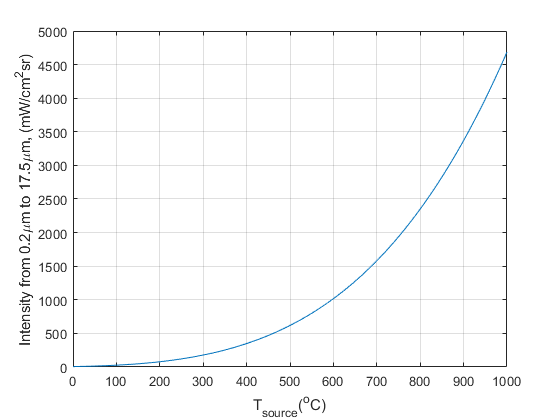

y1 = polyval(p,T_range);

plot(T_range-273,L)
ylabel(['Intensity from ',num2str(BP_wavelength(1)),'\mum to ',num2str(BP_wavelength(end)),'\mum, (mW/cm^{2}sr)'])
xlabel('T_{source}(^{o}C)')
grid on

theta = 0:90;
for j = 1:length(theta)
    for i = 1:length(L)
        L_surf(i,j) = L(i) .* cosd(theta(j));
    end
end
L_surf

L_surf = 	1.0e+03 *

    0.0061    0.0061    0.0061    0.0061    0.0060    0.0060    0.0060    0.0060    0.0060    0.0060    0.0060    0.0059    0.0059    0.0059    0.0059    0.0059    0.0058    0.0058    0.0058    0.0057    0.0057    0.0057    0.0056    0.0056    0.0055    0.0055    0.0054    0.0054    0.0053    0.0053    0.0052    0.0052    0.0051    0.0051    0.0050    0.0050    0.0049    0.0048    0.0048    0.0047    0.0046    0.0046    0.0045    0.0044    0.0044    0.0043    0.0042    0.0041    0.0041    0.0040
    0.0062    0.0062    0.0062    0.0062    0.0062    0.0061    0.0061    0.0061    0.0061    0.0061    0.0061    0.0061    0.0060    0.0060    0.0060    0.0060    0.0059    0.0059    0.0059    0.0058    0.0058    0.0058    0.0057    0.0057    0.0056    0.0056    0.0055    0.0055    0.0054    0.0054    0.0053    0.0053    0.0052    0.0052    0.0051    0.0051    0.0050    0.0049    0.0049    0.0048    0.0047    0.0047    0.0046    0.0045    0.0044    0.0044    0.0043    0.00

L_surf'

ans = 	1.0e+03 *

    0.0061    0.0062    0.0063    0.0064    0.0065    0.0066    0.0068    0.0069    0.0070    0.0071    0.0073    0.0074    0.0075    0.0077    0.0078    0.0079    0.0081    0.0082    0.0083    0.0085    0.0086    0.0088    0.0089    0.0091    0.0092    0.0094    0.0095    0.0097    0.0099    0.0100    0.0102    0.0104    0.0105    0.0107    0.0109    0.0110    0.0112    0.0114    0.0116    0.0117    0.0119    0.0121    0.0123    0.0125    0.0127    0.0129    0.0131    0.0133    0.0135    0.0137
    0.0061    0.0062    0.0063    0.0064    0.0065    0.0066    0.0068    0.0069    0.0070    0.0071    0.0073    0.0074    0.0075    0.0077    0.0078    0.0079    0.0081    0.0082    0.0083    0.0085    0.0086    0.0088    0.0089    0.0091    0.0092    0.0094    0.0095    0.0097    0.0099    0.0100    0.0102    0.0103    0.0105    0.0107    0.0109    0.0110    0.0112    0.0114    0.0116    0.0117    0.0119    0.0121    0.0123    0.0125    0.0127    0.0129    0.0131    0.0133 

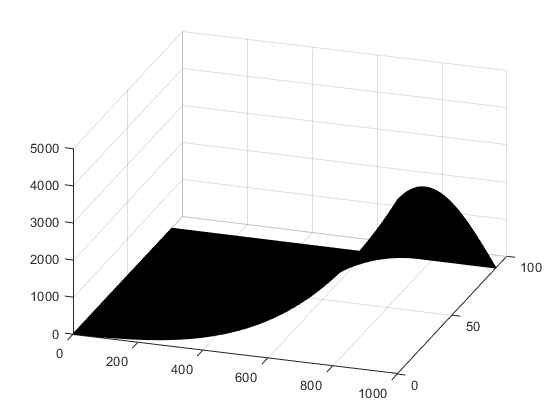

surf(T_range-273,theta,L_surf')

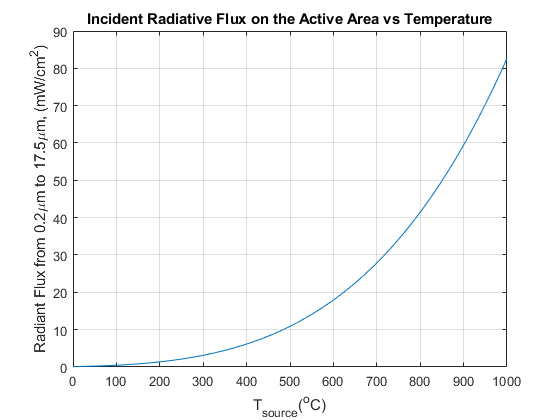


Phi_uA = L * A_i * sr * Avg_trans;%mW/cm

plot(T_range-273,Phi_uA)
ylabel(['Radiant Flux from ',num2str(BP_wavelength(1)),'\mum to ',num2str(BP_wavelength(end)),'\mum, (mW/cm^{2})'])
xlabel('T_{source}(^{o}C)')
title('Incident Radiative Flux on the Active Area vs Temperature')
grid on

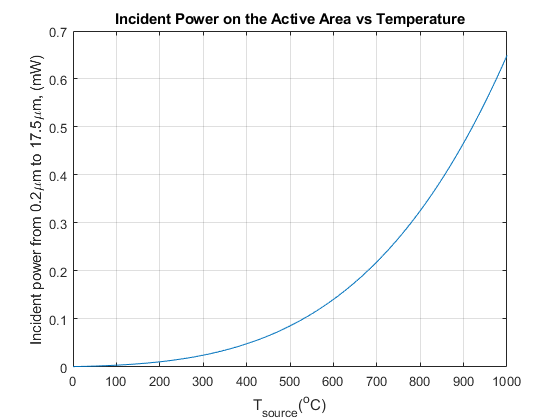

Phi = Phi_uA * A_j ;%mW

plot(T_range-273,Phi)
ylabel(['Incident power from ',num2str(BP_wavelength(1)),'\mum to ',num2str(BP_wavelength(end)),'\mum, (mW)'])
xlabel('T_{source}(^{o}C)')
title('Incident Power on the Active Area vs Temperature')
grid on

dV = (Phi - Phi(1)) .* Responsivity %mV

dV =          0    0.0004    0.0007    0.0011    0.0015    0.0019    0.0023    0.0027    0.0031    0.0035    0.0039    0.0043    0.0047    0.0051    0.0056    0.0060    0.0065    0.0069    0.0074    0.0078    0.0083    0.0088    0.0092    0.0097    0.0102    0.0107    0.0112    0.0117    0.0122    0.0127    0.0133    0.0138    0.0143    0.0149    0.0154    0.0160    0.0165    0.0171    0.0177    0.0183    0.0188    0.0194    0.0200    0.0206    0.0213    0.0219    0.0225    0.0231    0.0238    0.0244


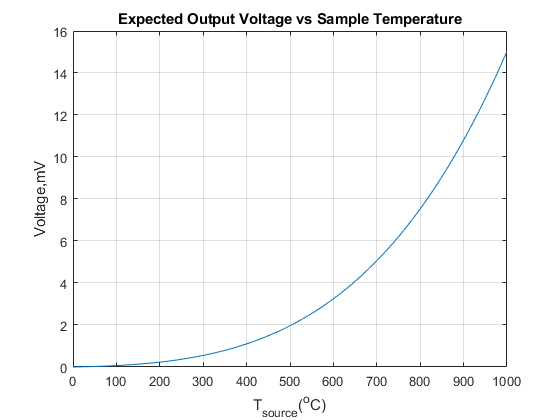

plot(T_range-273,dV)
title('Expected Output Voltage vs Sample Temperature')
ylabel('Voltage,mV')
xlabel('T_{source}(^{o}C)')
grid on

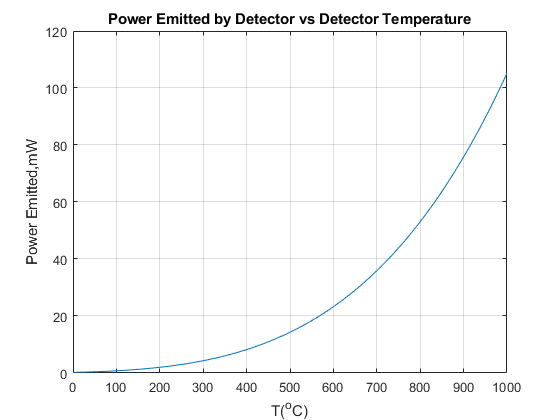


sigma = 5.6697*(10^-9);
epsilon = .9;

Phi_emitted = sigma * epsilon* (T_range.^4);
q_emitted = Phi_emitted * A_j;%mW

plot(T_range-273,q_emitted)
ylabel('Power Emitted,mW')
xlabel('T(^{o}C)')
title('Power Emitted by Detector vs Detector Temperature')
grid on

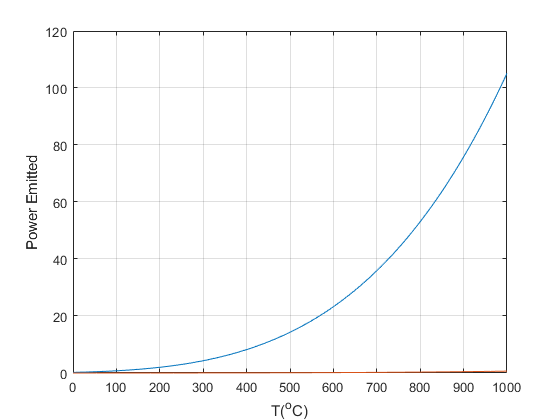

plot(T_range-273,q_emitted,T_range-273,Phi)
ylabel('Power Emitted')
xlabel('T(^{o}C)')
grid on

## If parabolic mirror is used:

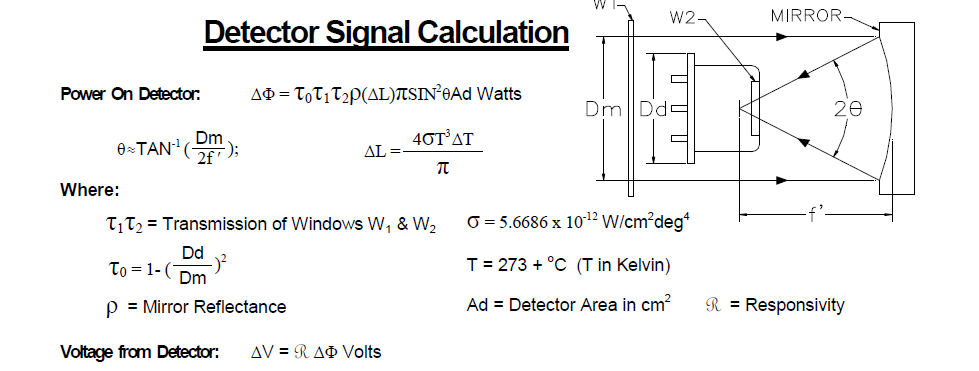

#### May be necessary if maximum power on detector could exceed .1W/cm^2.

a =0.3;
D_m = D_d + a

D_m = 1.3236

rho = .9;
foc = 5;
theta = atand(D_m./(2*foc));
tau_o = 1 - ((D_d./D_m).^2)

tau_o = 0.4019


Phi_uA2 = Avg_trans * rho * L * pi * (sind(theta)^2)  

Phi_uA2 =     0.2684    0.2735    0.2786    0.2837    0.2890    0.2943    0.2996    0.3051    0.3106    0.3162    0.3219    0.3276    0.3334    0.3393    0.3453    0.3513    0.3574    0.3636    0.3699    0.3762    0.3826    0.3891    0.3957    0.4023    0.4091    0.4159    0.4228    0.4298    0.4369    0.4440    0.4512    0.4586    0.4660    0.4734    0.4810    0.4887    0.4964    0.5043    0.5122    0.5202    0.5283    0.5365    0.5448    0.5532    0.5617    0.5702    0.5789    0.5877    0.5965    0.6055


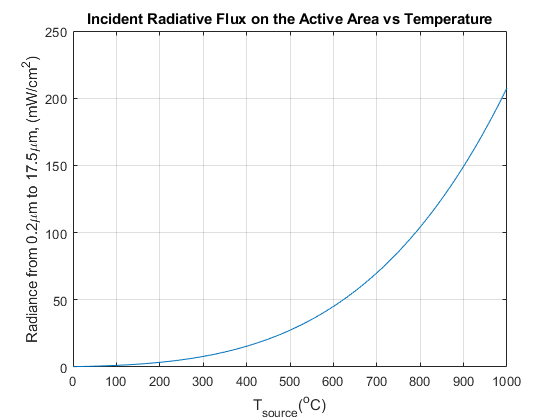


plot(T_range-273,Phi_uA2)
ylabel(['Radiance from ',num2str(BP_wavelength(1)),'\mum to ',num2str(BP_wavelength(end)),'\mum, (mW/cm^{2})'])
xlabel('T_{source}(^{o}C)')
title('Incident Radiative Flux on the Active Area vs Temperature')
grid on

## Thermistor Integration

*This is a recommended reference junction correction circuit from Dexter, but we are going to just do the calculations on the computer.

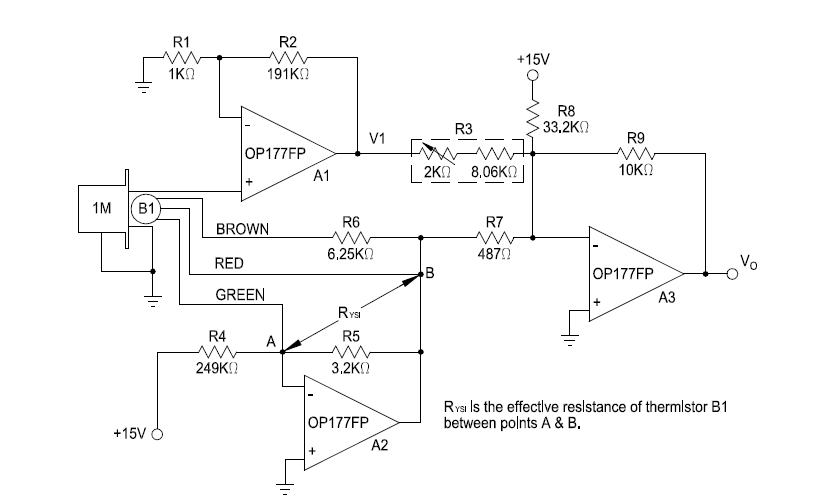

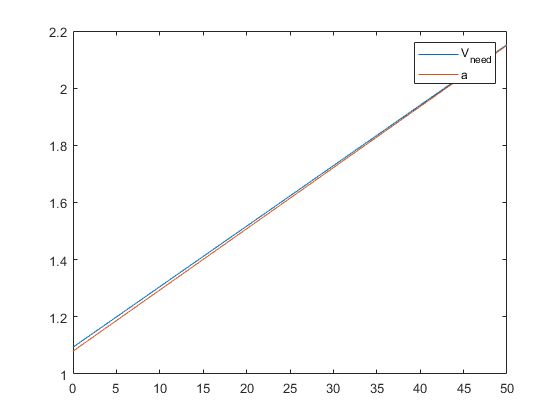

R1 = 1 * 1000;
R1 = 191 * 1000;
R3 =2.8 * 1000;
R4 = 249 * 1000;
R5 = 3.2 * 1000;
R6 = 6.25 * 1000;
R7 = 0.487 * 1000;
R8 = 33.2 * 1000;
R9 = 10 * 1000;
V_i = 15;
T_c = 0:50;

T_d = T_c;
110+273;
R_YSI = 2768.23 - 17.115.*T_c;
V_T = f.Inv_Amp(V_i,R4,R_YSI);
%Term_1 = 
%Term_2 = 
Term_3 = f.Inv_Amp(V_T,R7,R9);
Term_4 = f.Inv_Amp(V_i,R8,R9);

V_need = -(Term_3 + Term_4);

V_o_max = 10;
Max_T = 200 + 273;
Inst_Const = -V_o_max./(Max_T^4);


a = .0214*T_c + 1.08;
R9*V_i/R8;
R9*15/(R7*R4);

%R3_req = 
b = -Inst_Const .* T_d.^4;
polyfit(T_c,V_need,2);

plot(T_c,V_need,T_c,a)
legend('V_{need}','a')